# **demo14 of Im2mesh package**

demo14 - How to use polyshape object to define multi-part geometry for mesh generation

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 350; height = 350;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function poly2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Polyshape

Polyshape is a MATLAB built-in object for polygon-like shapes. We can use object functions of polyshape to create single-part or multi-part geometry. Please refer to the following webpage about object functions of polyshape.

[https://www.mathworks.com/help/matlab/ref/polyshape.html](https://www.mathworks.com/help/matlab/ref/polyshape.html)

## Single-part geometry

### A polyshape

Let's create a polyshape (for a single-part geometry). 

Suppose we want a square with a hole.

% unit square
vertex = [ 0 0; 1 0; 1 1; 0 1 ];
psUnitSq = polyshape(vertex);

Scale the unit square with respect to its centroid to create a tiny square, and rotate.

% scale
[x,y] = centroid(psUnitSq);
refpoint = [x,y];
scale_factor = 0.15;
psSqTiny = scale(psUnitSq, scale_factor, refpoint);

% rotate
[x,y] = centroid(psSqTiny);
refpoint = [x,y];
psSqTiny = rotate(psSqTiny, 45, refpoint);

Perform boolean operation to create a square with a hole.

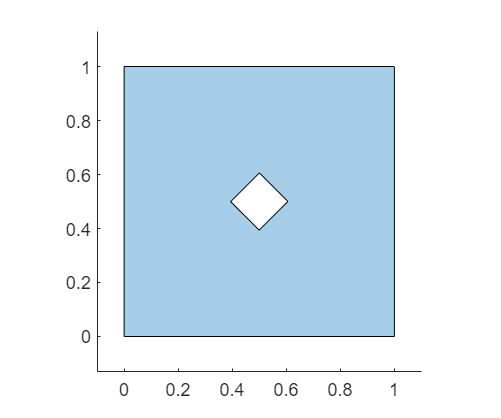

psSqHole = subtract(psUnitSq, psSqTiny);

plot(psSqHole); 
axis equal

### Polygonal boundary

We use function polyshape2bound to convert a cell array of polyshape to a cell array of polygonal boundary. 

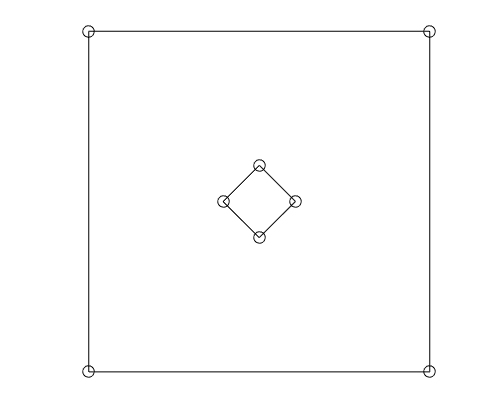

psCell = {psSqHole}; % psCell is a cell array of polyshape

bounds = polyshape2bound(psCell);

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

### Generate mesh via MESH2D

To generate mesh, we use function poly2mesh.

Note that function poly2mesh uses [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda) as mesh generator.

[ poly_node, poly_edge ] = getPolyNodeEdge( bounds );

hmax = 500; 
mesh_kind = 'delaunay'; % method used to create mesh size function
grad_limit = 0.25;
[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          2                 12                  8
          5                 20                 28


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          3                 20                  8
          8                 20                 54


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                  5                 54



Plot mesh.

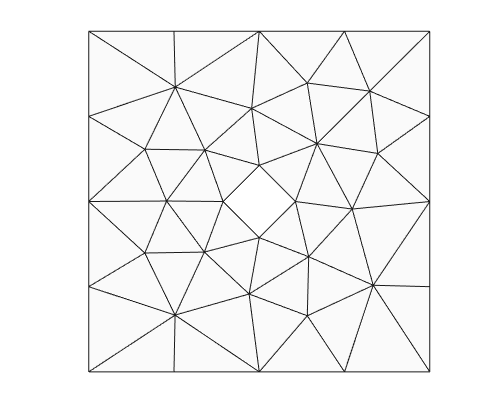

plotMeshes(vert,tria,tnum);

We can adjust hmax and grad_limit to change the mesh size.

### Generate mesh via Gmsh

**To use Gmsh as mesh generator, we need to download Gmsh (**[**https://gmsh.info**](https://gmsh.info)**) and un-zip.**

We need to know the location of gmesh.exe

% for example
path_to_gmsh = 'C:\Users\Jason\Downloads\gmsh-4.13.1-Windows64\gmsh.exe';

We can use Gmsh to generate triangular or quadrilateral mesh. Please refer to 'Im2mesh_GUI Tutorial.pdf' and Gmsh manual about how to choose meshing parameters. Please refer to demo13 about the meanings of the following functions.

Let's generate unstructured quadrilateral mesh.

[ phaseLoops, vertex, edge ] = bound2SurfaceLoop( bounds );
point = vertex;
line = edge;

% setup parameters
opt = [];   % reset
opt.sizeMin = 0.01;
opt.sizeMax = 0.1;
opt.algthm = 8;
opt.recombAll = 1;
opt.recombAlgthm = 3;
opt.eleOrder = 1;

path_to_geo = 'gmshTemp.geo';
printGeo( phaseLoops, point, line, opt, path_to_geo );

path_to_m = 'gmshTemp.m';
verbosity = 3;
str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_m, verbosity );
system(str);

% run m file
run(path_to_m)
% struct variable 'msh' in the workspace of MATLAB
msh

msh = struct with fields:
    nbNod: 136
      POS: [136×3 double]
      MAX: [1 1 0]
      MIN: [0 0 0]
    QUADS: [112×5 double]


Before ploting the mesh, we need to do some processing to the mesh data. 

vert = msh.POS(:,1:2);
ele = msh.QUADS(:,1:end-1);
tnum = msh.QUADS(:,end);

% flip for correct signs
area = quadarea( vert, ele );
ele(area<0.,:) = ele( area<0., [1,4,3,2] );

Plot mesh.

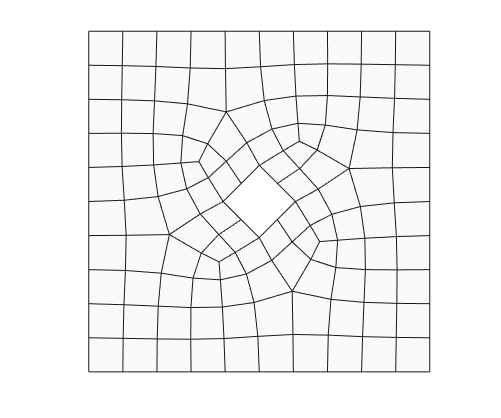

plotMeshes( vert, ele, tnum )

Awesome! Please refer to demo13 about how to evaluate mesh quality.

## Mesh seed

It's possible to add mesh seed to the polygonal boundary before mesh generation. Please refer to demo16 about how to add mesh seeds.

Seeds are defined as markers that you place along the edges of a region to specify the target mesh density in that region.

## Multi-part geometry

### Multiple polyshapes

Let's create multiple polyshapes for multi-part geometry.

clearvars

Start with a unit square.

vertex = [ 0 0; 1 0; 1 1; 0 1 ];
psUnitSq = polyshape(vertex);

Create three rods - A B C, and combine them using function union.

psRodBase = scale( psUnitSq, [1, 0.05]);

psRodA = rotate( psRodBase, 155 );
psRodA = translate( psRodA, [0.6 0.8] );
psRodB = translate( psRodBase, [0.1 0.9] );
psRodC = translate( psRodBase, [-0.1 0.5] );

psRodABC = union([ psRodA; psRodB; psRodC ]);

Create a circle.

t = 0.05:0.03:2*pi;
x1 = 0.8 + 0.15*cos(t);
y1 = 0.95 + 0.15*sin(t);
psCircle = polyshape(x1,y1);

Plot them together.

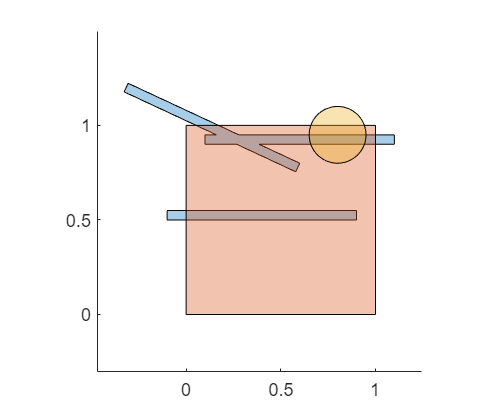

plot( [psRodABC; psUnitSq; psCircle] ); 
axis equal

We saw that they are overlapped.

### Boolean operations

We use boolean operations to remove overlapped regions.

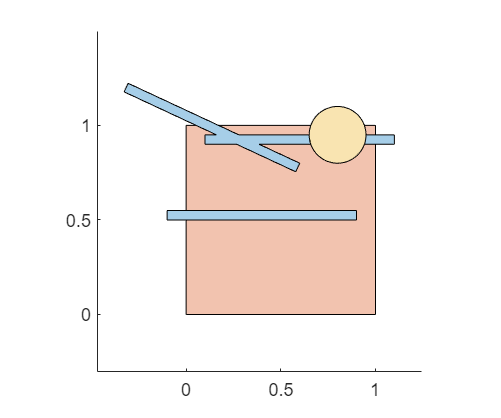

psBlock = subtract( psUnitSq, psRodABC );
psBlock = subtract( psBlock, psCircle );

psRodABC = subtract( psRodABC, psCircle );

plot( [psRodABC; psBlock; psCircle] ); 
axis equal

### Cell array of polyshape

We put them into a cell array - psCell. Each element in psCell represent different parts. It's like labelling.

psCell = { psRodABC; psBlock; psCircle };

% plot psCell
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

### Add intersect points

Polyshape objects are not able to find intersect points automatically. Therefore, we convert the cell array of polyshape 'psCell' to a cell array of polygonal boundaries 'bounds', and use function addIntersectPnts to add intersect points to 'bounds'. 

Note that if we don't add intersect points, mesh generation will fail.

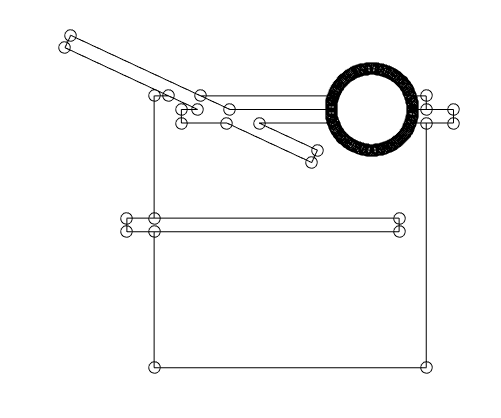

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;   % distance tolerance for intersect
boundsNew = addIntersectPnts( bounds, tol_intersect );

% plot boundaries and show all vertices
plotBounds(boundsNew,false,'ko-')

We saw that there are a lot of vertices on the circle.

### Simplify boundaries

We want to reduce the number of vertices on the circle.

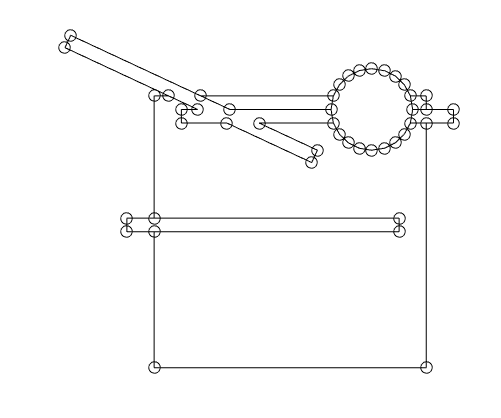

boundsCtrlP = getCtrlPnts( boundsNew, false );

tolerance = 0.003;  % for Douglas-Peucker polyline simplification
boundsSimplified = simplifyBounds( boundsCtrlP, tolerance, 0 );

% show all vertices
plotBounds(boundsSimplified,false,'ko-')

Awesome! We saw that the number of vertices on the circle reduced a lot.

Note that you need to adjust the value of tolerance to achieve your desired reduction.

### Generate mesh via MESH2D

To generate mesh, we use function poly2mesh.

Note that function poly2mesh uses [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda) as mesh generator.

[ poly_node, poly_edge ] = getPolyNodeEdge( boundsSimplified );

hmax = 500; 
mesh_kind = 'delaunay'; % method used to create mesh size function
grad_limit = 0.25;
[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                 86                 65
         10                102                172
         11                102                174


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                140                 65
         10                157                444
         14                157                506


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                 89                492
          8                  0                492



Plot mesh.

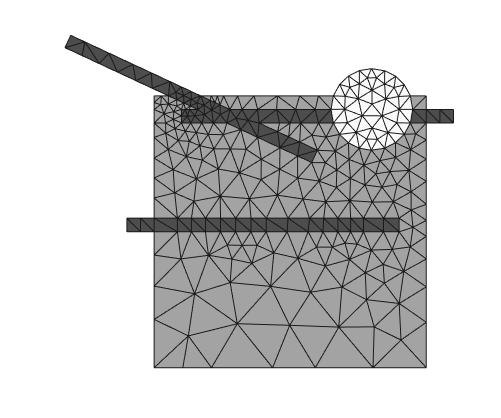

plotMeshes(vert,tria,tnum);

Awesome!

We saw that the mesh in the rod is very coarse. It's possible to refine mesh near a specific polygon boundary. Please refer to demo04 and demo16.

### Generate mesh via Gmsh

**To use Gmsh as mesh generator, we need to download Gmsh (**[**https://gmsh.info**](https://gmsh.info)**) and un-zip.**

We need to know the location of gmesh.exe

% for example
path_to_gmsh = 'C:\Users\Jason\Downloads\gmsh-4.13.1-Windows64\gmsh.exe';

We can use Gmsh to generate triangular or quadrilateral mesh. Please refer to 'Im2mesh_GUI Tutorial.pdf' and Gmsh manual about how to choose meshing parameters. Please refer to demo13 about the meanings of the following functions.

[ phaseLoops, vertex, edge ] = bound2SurfaceLoop( boundsSimplified );
point = vertex;
line = edge;

% setup parameters
opt = [];   % reset
opt.sizeMin = 0.01;
opt.sizeMax = 0.07;
opt.algthm = 8;
opt.recombAll = 1;
opt.recombAlgthm = 3;
opt.eleOrder = 1;

path_to_geo = 'gmshTemp.geo';
printGeo( phaseLoops, point, line, opt, path_to_geo );

path_to_m = 'gmshTemp.m';
verbosity = 3;
str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_m, verbosity );
system(str);


% run m file
run(path_to_m)
% struct variable 'msh' in the workspace of MATLAB
msh

msh = struct with fields:
    nbNod: 659
      POS: [659×3 double]
      MAX: [1.1000 1.2226 0]
      MIN: [-0.3274 0 0]
    QUADS: [606×5 double]


Before ploting the mesh, we need to do some processing to the mesh data. 

vert = msh.POS(:,1:2);
ele = msh.QUADS(:,1:end-1);
tnum = msh.QUADS(:,end);

% flip for correct signs
area = quadarea( vert, ele );
ele(area<0.,:) = ele( area<0., [1,4,3,2] );

Plot mesh.

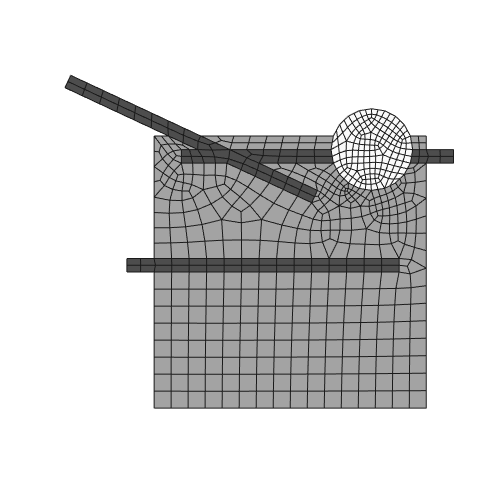

plotMeshes( vert, ele, tnum )

Awesome! Please refer to demo13 about how to evaluate mesh quality.

## Comments

It's possible to generate mesh for multi-part geometry via Matlab built-in function generateMesh (need PDE toolbox).

However, function generateMesh has bad interface for multi-part geometry. Here, we use function poly2meshBuiltIn as interface. Inside poly2meshBuiltIn, it's function generateMesh. Note that function poly2meshBuiltIn may crash occasionally.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo